clear
clc

Step.1 Create systems

%transfer functions
s = tf('s');
G1 = 3/(s^3 + 5*s^2 + 12*s);
G2 = 1/(s^3 + 7*s^2 + 4*s);
G3 = 1/(s^3 + 7*s^2 + 12*s);
G4 = 3/(s^3 + 5*s^2 + 4*s);

Step.2 Determining polynomials representing worst case

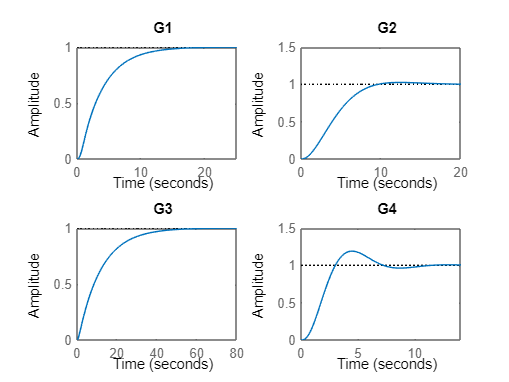

%step responses separetly
figure();
subplot(2,2,1);
step(feedback(G1,1)); title('G1'); xlim([0 25]);
subplot(2,2,2);
step(feedback(G2,1)); title('G2'); xlim([0 20]); ylim([0 1.5]);
subplot(2,2,3);
step(feedback(G3,1)); title('G3'); xlim([0 80]);
subplot(2,2,4);
step(feedback(G4,1)); title('G4'); ylim([0 1.5]);

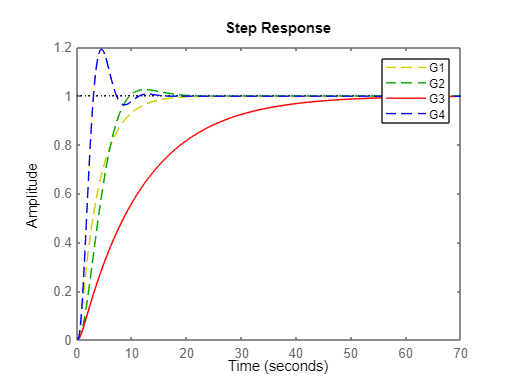

%plotting responses on one plot
figure();
step(feedback(G1,1),'y--'); hold on;
step(feedback(G2,1),'g--'); hold on;
step(feedback(G3,1),'r'); hold on;
step(feedback(G4,1),'b--'); hold on;
legend('G1', 'G2', 'G3', 'G4');

%saving characteristics of each plot
S1 = stepinfo(feedback(G1,1));
S2 = stepinfo(feedback(G2,1));
S3 = stepinfo(feedback(G3,1));
S4 = stepinfo(feedback(G4,1));
%preparing result table
Res=zeros(4);
Res(1,1)=S1.PeakTime;
Res(1,2)=S1.Overshoot;
Res(1,3)=S1.RiseTime;
Res(1,4)=S1.SettlingTime;

Res(2,1)=S2.PeakTime;
Res(2,2)=S2.Overshoot;
Res(2,3)=S2.RiseTime;
Res(2,4)=S2.SettlingTime;

Res(3,1)=S3.PeakTime;
Res(3,2)=S3.Overshoot;
Res(3,3)=S3.RiseTime;
Res(3,4)=S3.SettlingTime;

Res(4,1)=S4.PeakTime;
Res(4,2)=S4.Overshoot;
Res(4,3)=S4.RiseTime;
Res(4,4)=S4.SettlingTime;
%comparaison of the results (Peak time, Overshoot, RiseTime, SettlingTime
%from left to right
Res

Res =    22.9920         0    7.7928   14.3607
   12.4206    2.5409    5.8843   14.4200
   83.4243         0   25.0431   45.1875
    4.4911   19.0146    1.9164   10.0848


Step.3 Designing a robust PID controller for the worst-case plant

a) Selecting natural frequency

%selecting natural frequency based on the equations
%beacouse of the condition that PeakTime response is max 2.5s, we choose omega = 2.5 rad/s 
%additionally the condition is that omega >= 2.2 rad/s
wn = 2.5;

b) Determining PID controller parameters 

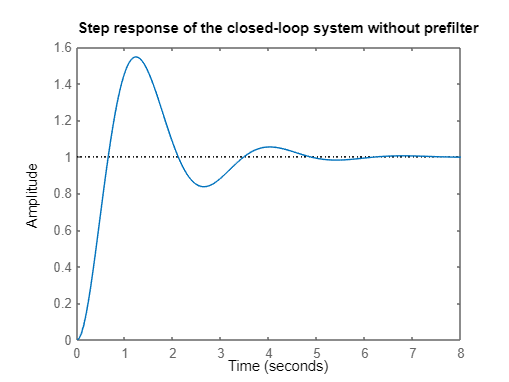

%Gains of the PID controller from the table
Kp = 2.7*wn^3;
Ki = wn^4;
Kd = 3.4*wn^2 - 12;
Gc = Kp + Ki/s + Kd*s;
T1 = feedback(Gc*G3,1);
figure();
step(T1);
title('Step response of the closed-loop system without prefilter');

stepinfo(T1)

ans = struct with fields:
         RiseTime: 0.4408
    TransientTime: 4.6016
     SettlingTime: 4.6016
      SettlingMin: 0.8371
      SettlingMax: 1.5463
        Overshoot: 54.6283
       Undershoot: 0
             Peak: 1.5463
         PeakTime: 1.2178


%overshoot is too big so we add filter

c) Determining a prefilter Gp(s) to remove all the zeros

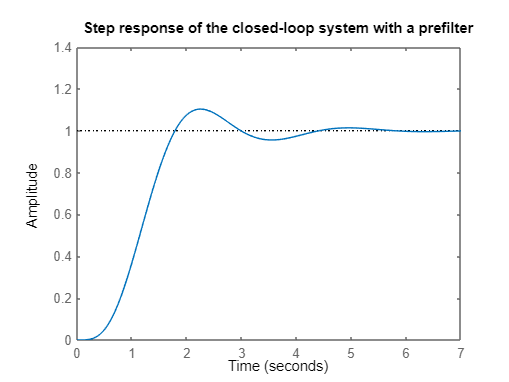

Gp = Ki/(Kd*s^2 + Kp*s + Ki);
T1 = feedback(Gc*G3,1);
T = T1*Gp;
figure();
step(T); ylim([0 1.4]);
title('Step response of the closed-loop system with a prefilter');

stepinfo(T)

ans = struct with fields:
         RiseTime: 0.9897
    TransientTime: 4.0911
     SettlingTime: 4.0911
      SettlingMin: 0.9039
      SettlingMax: 1.1032
        Overshoot: 10.3238
       Undershoot: 0
             Peak: 1.1032
         PeakTime: 2.2399


ALL of this is the INITIAL assumption (omega n = 2.5), the optimal solution is found for omega n = 3.4.

Below we can see the plots of the step in such a case

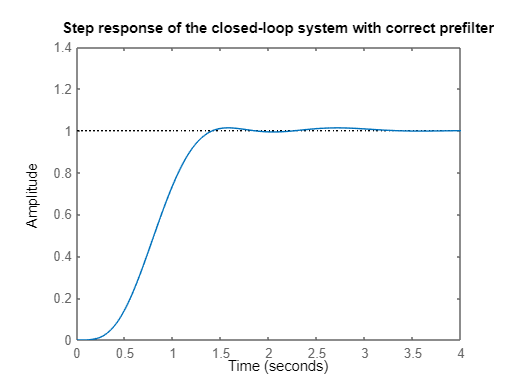

wn = 3.4;
Kp = 2.7*wn^3;
Ki = wn^4;
Kd = 3.4*wn^2 - 12;
Gc = Kp + Ki/s + Kd*s;
Gp = Ki/(Kd*s^2 + Kp*s + Ki);
T1 = feedback(Gc*G3,1);
T = T1*Gp;
figure();
step(T); ylim([0 1.4]);
title('Step response of the closed-loop system with correct prefilter');

stepinfo(T)

ans = struct with fields:
         RiseTime: 0.7362
    TransientTime: 1.3349
     SettlingTime: 1.3349
      SettlingMin: 0.9168
      SettlingMax: 1.0137
        Overshoot: 1.3704
       Undershoot: 0
             Peak: 1.0137
         PeakTime: 1.5591


Now we have to compare step responses for the closed loop prefiltered system obtained from  G3(s) and from nominal plant (K=2, p=2).

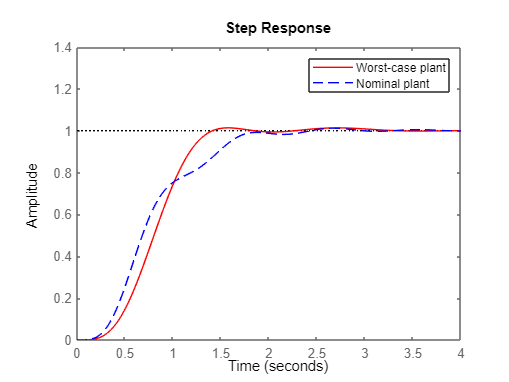

K = 2;
p = 2;
G_nominal = K/(s*(s+p)*(s+4));
T1_nominal = feedback(Gc*G_nominal,1);
T_nominal = T1_nominal*Gp;
figure();
step(T, 'r'); ylim([0 1.4]); hold on;
step(T_nominal, 'b--');
legend('Worst-case plant', 'Nominal plant');

stepinfo(T_nominal)

ans = struct with fields:
         RiseTime: 1.1125
    TransientTime: 1.7210
     SettlingTime: 1.7210
      SettlingMin: 0.9052
      SettlingMax: 1.0120
        Overshoot: 1.2030
       Undershoot: 0
             Peak: 1.0120
         PeakTime: 2.6582


Step.4 Test the designed robust PID controller with the prefilter Gp(s) for the four special conditions.

a) K=1 p=1 b) K=1 p=3 c) K=3 p=1 d) K=3 p=3

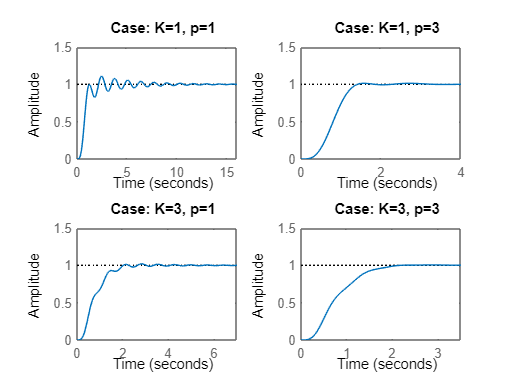

%First case K=1, p=1
C1 = 1/(s*(s+1)*(s+4));
T_C1 = feedback(Gc*C1,1);
T1 = T_C1*Gp;
%Second case K=1, p=3
C2 = 1/(s*(s+3)*(s+4));
T_C2 = feedback(Gc*C2,1);
T2 = T_C2*Gp;
%Third case K=3, p=1
C3 = 3/(s*(s+1)*(s+4));
T_C3 = feedback(Gc*C3,1);
T3 = T_C3*Gp;
%Fourth case K=3, p=3
C4 = 3/(s*(s+3)*(s+4));
T_C4 = feedback(Gc*C4,1);
T4 = T_C4*Gp;
%plotting results
figure();
subplot(2,2,1); step(T1); title('Case: K=1, p=1'); ylim([0 1.5]);
subplot(2,2,2); step(T2); title('Case: K=1, p=3'); ylim([0 1.5]);
subplot(2,2,3); step(T3); title('Case: K=3, p=1'); ylim([0 1.5]);
subplot(2,2,4); step(T4); title('Case: K=3, p=3'); ylim([0 1.5]);

%saving results
S1 = stepinfo(T1);
S2 = stepinfo(T2);
S3 = stepinfo(T3);
S4 = stepinfo(T4);
%preparing result table
Res2=zeros(4);
Res2(1,1)=S1.PeakTime;
Res2(1,2)=S1.Overshoot;
Res2(1,3)=S1.RiseTime;
Res2(1,4)=S1.SettlingTime;

Res2(2,1)=S2.PeakTime;
Res2(2,2)=S2.Overshoot;
Res2(2,3)=S2.RiseTime;
Res2(2,4)=S2.SettlingTime;

Res2(3,1)=S3.PeakTime;
Res2(3,2)=S3.Overshoot;
Res2(3,3)=S3.RiseTime;
Res2(3,4)=S3.SettlingTime;

Res2(4,1)=S4.PeakTime;
Res2(4,2)=S4.Overshoot;
Res2(4,3)=S4.RiseTime;
Res2(4,4)=S4.SettlingTime;
%comparaison of the results (Peak time, Overshoot, RiseTime, SettlingTime
%from left to right
Res2

Res2 =     2.4587   10.9336    0.6056    8.4515
    1.5591    1.3704    0.7362    1.3349
    2.8249    1.9885    1.0267    2.5166
    2.8475    0.5572    1.0694    1.9197
